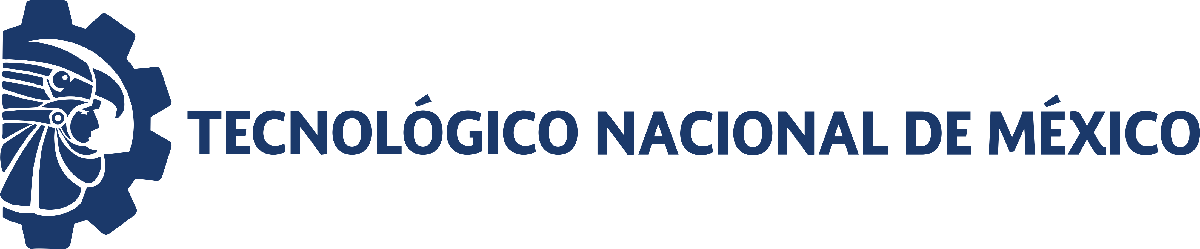                                 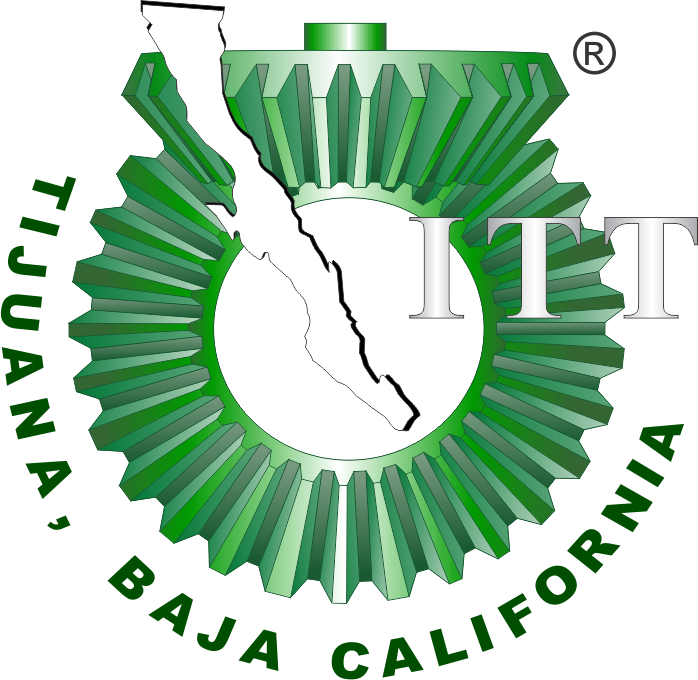

# Práctica tres: Sistema musculoesqueletico

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

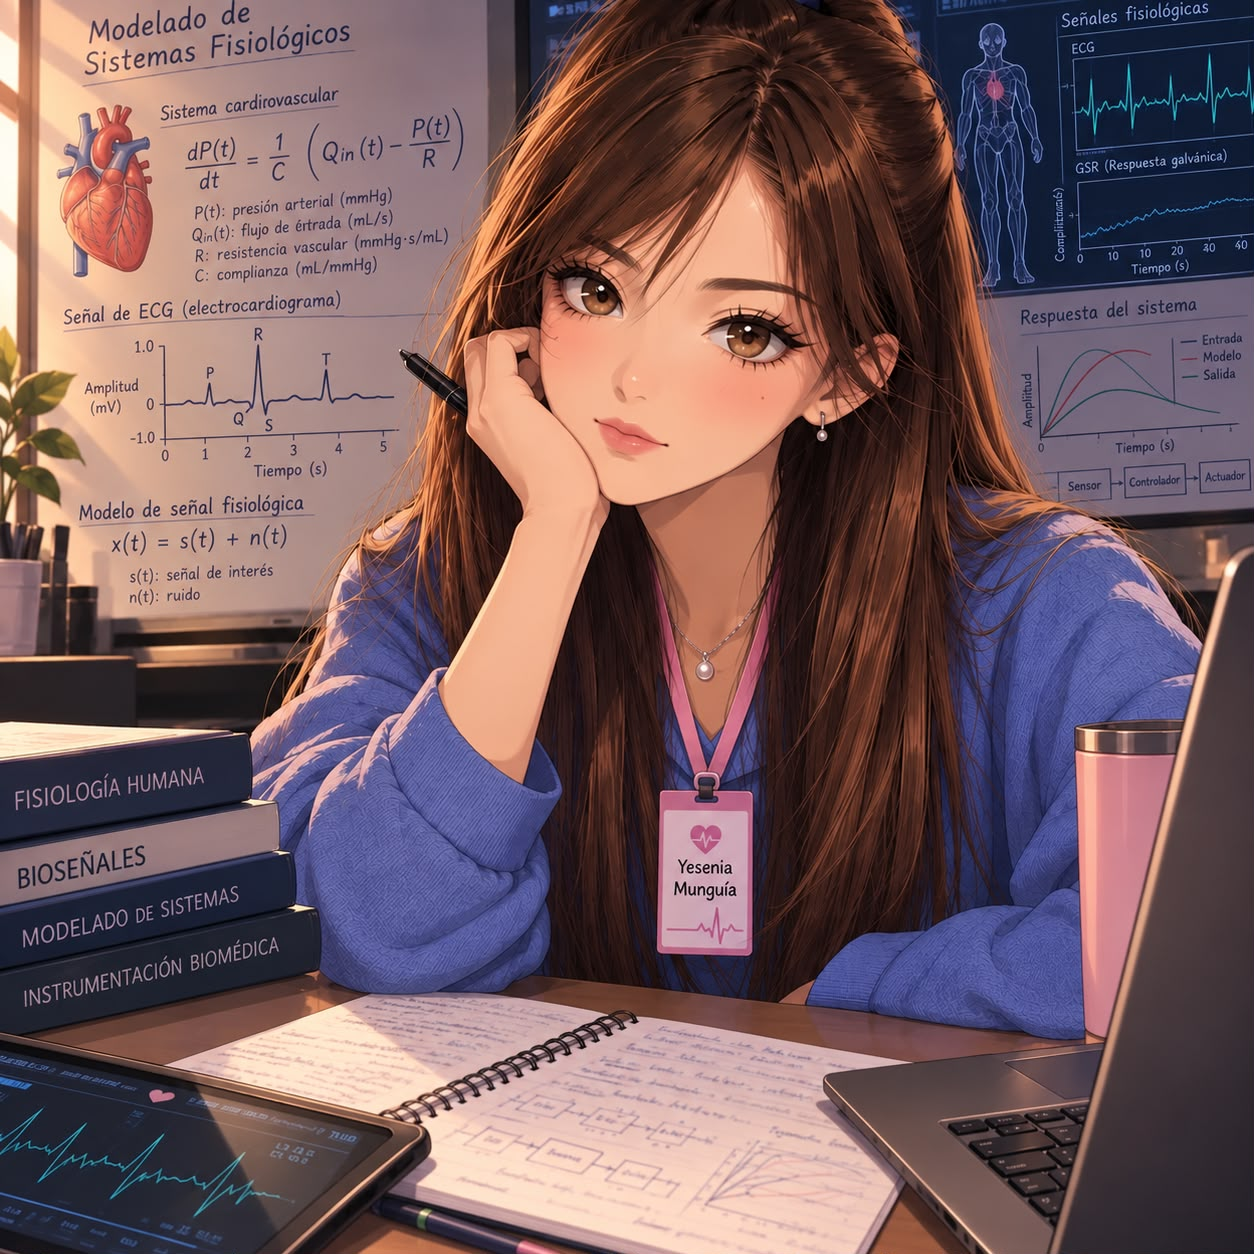

Nombre del alumno: **Munguia Silva Yesenia Isamar**

Número de control: **23212217**

Correo institucional:** l23212217@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10'

tend = '10'

file = 'sistema1'

file = 'sistema1'

open_system(file)
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
X = sim(file,parameters);

## Respuesta al impuslo unitario

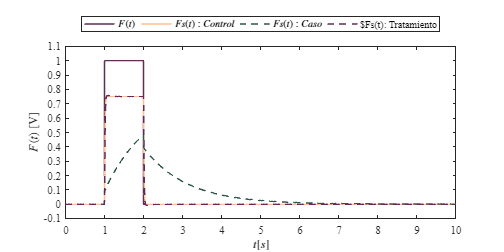

plotsignals(X.t,X.F,X.Fsx,X.Fsy,X.PID)

## Funcion: Respuestas de la simulacion

function plotsignals (t, F, Fsx,Fsy,PID)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [97,45,83]/255;
    clr2 = [255,190,145]/255;
    clr3 = [44,87,69]/255;
    order = [clr1;clr2;clr3]; colororder(order)
    
    plot(t,F,'-',t,Fsx,'-',t,Fsy,'--',t,PID,'--','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1e3:length(t));
    L = legend('$F(t)$','$Fs(t): Control$','$Fs(t): Caso$','$Fs(t): Tratamiento');

    set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
    xlabel('$t[s]$','interpreter','latex') 
    ylabel('$F(t)$ [V]','interpreter','latex')

    xlim([0 10]); xticks(0:1:10)
    ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)


    exportgraphics(gcf, 'Caso_Control_matlab.pdf','contenttype','vector')
end